% Oscillator Design
% Loading S Params of Transistor
f = SParamsFromDatasheetVDS6VandVGS0.frequencyGHz*1e9;
Z0 = 50;
f0 = 2e9;
idx = 2; % index of frequency = f0
omega0 = 2*pi*f0;

S11 = SParamsFromDatasheetVDS6VandVGS0.S11_Magnitude.*exp(j*SParamsFromDatasheetVDS6VandVGS0.S11_Phase*pi/180);
S12 = SParamsFromDatasheetVDS6VandVGS0.S12_Magnitude.*exp(j*SParamsFromDatasheetVDS6VandVGS0.S12_Phase*pi/180);
S21 = SParamsFromDatasheetVDS6VandVGS0.S21_Magnitude.*exp(j*SParamsFromDatasheetVDS6VandVGS0.S21_Phase*pi/180);
S22 = SParamsFromDatasheetVDS6VandVGS0.S22_Magnitude.*exp(j*SParamsFromDatasheetVDS6VandVGS0.S22_Phase*pi/180);

numberOfFreqPoints = length(S11);
sizeOfS = size(S11);

S = [S11(idx), S12(idx); S21(idx), S22(idx)];

% Pi Type Designs
% Y params

% Y = {zeros(sizeOfS), zeros(sizeOfS); zeros(sizeOfS), zeros(sizeOfS)};
% 
% for k = 1:numberOfFreqPoints
%     Stemp = [S{1,1}(k), S{1,2}(k); S{2,1}(k), S{2,2}(k)];
%     Ytemp = s2y(Stemp, Z0);
%     Y{1,1}(k) = Ytemp(1,1);
%     Y{1,2}(k) = Ytemp(1,2);
%     Y{2,1}(k) = Ytemp(2,1);
%     Y{2,2}(k) = Ytemp(2,2);
% end

Y = s2y(S, Z0);

% Generating the parameters
A = -(Y(2,1) + conj(Y(1,2)))/(2*real(Y(2,2)));
C1 = -real(Y(1,1) + A*Y(1,2));
C2 = -imag(Y(1,1) + A*Y(1,2));
C3 = -real(Y(2,1) + A*Y(2,2));
C4 = -imag(Y(2,1) + A*Y(2,2));


% Design #1

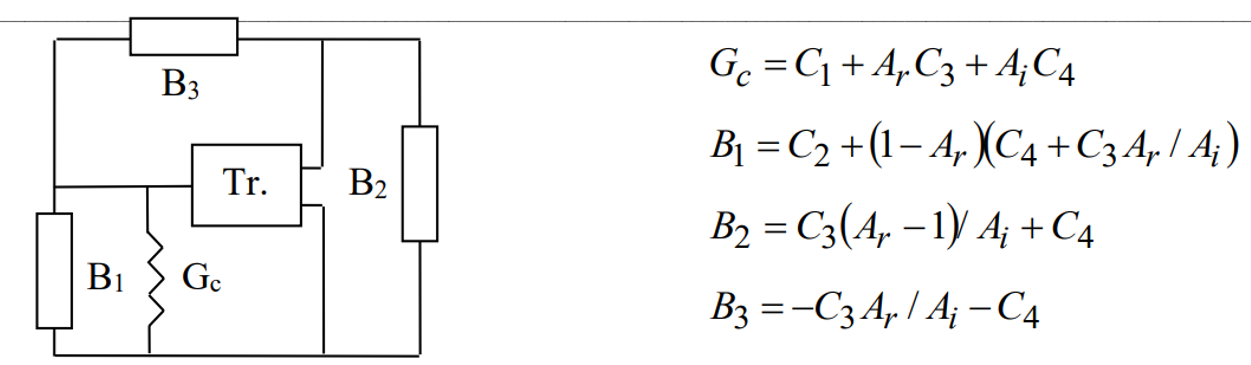

design1.Gc = C1 + real(A)*C3 + imag(A)*C4;
design1.B1 = C2 + (1-real(A))*(C4 + C3*real(A)/imag(A));
design1.B2 = C3*(real(A)-1)/imag(A) + C4;
design1.B3 = -C3*real(A)/imag(A) - C4;

design1.Rc = 1/design1.Gc;
design1.X1 = 1/design1.B1;
design1.X2 = 1/design1.B2;
design1.X3 = 1/design1.B3;

if design1.X1 > 0
    design1.L1 = design1.X1/omega0;
else
    design1.C1 = -1/(omega0*design1.X1);
end

if design1.X2 > 0
    design1.L2 = design1.X2/omega0;
else
    design1.C2 = -1/(omega0*design1.X2);
end

if design1.X3 > 0
    design1.L3 = design1.X3/omega0;
else
    design1.C3 = -1/(omega0*design1.X3);
end


% Design #2

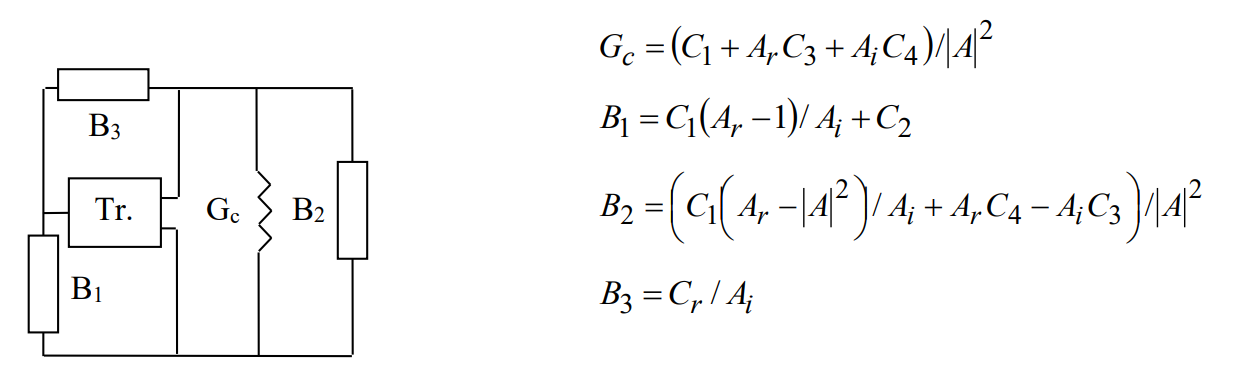

design2.Gc = (C1 + real(A)*C3 + imag(A)*C4)/abs(A)^2;
design2.B1 = C1*(real(A) - 1)/imag(A) + C2;
design2.B2 = (C1*(real(A) - abs(A)^2)/imag(A) + real(A)*C4 - imag(A)*C3)/abs(A)^2;
design2.B3 = C1/imag(A); % Typo in notes: Assuming Cr = C1

design2.Rc = 1/design2.Gc;
design2.X1 = 1/design2.B1;
design2.X2 = 1/design2.B2;
design2.X3 = 1/design2.B3;

if design2.X1 > 0
    design2.L1 = design2.X1/omega0;
else
    design2.C1 = -1/(omega0*design2.X1);
end

if design2.X2 > 0
    design2.L2 = design2.X2/omega0;
else
    design2.C2 = -1/(omega0*design2.X2);
end

if design2.X3 > 0
    design2.L3 = design2.X3/omega0;
else
    design2.C3 = -1/(omega0*design2.X3);
end



% Design 3

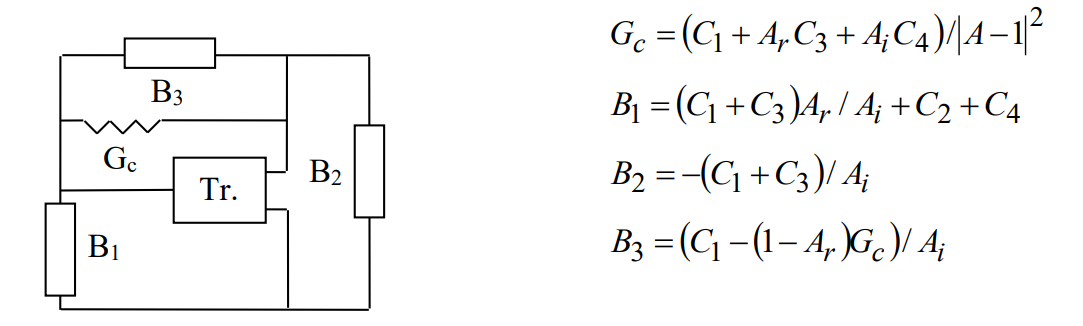

design3.Gc = (C1 + real(A)*C3 + imag(A)*C4)/abs(A-1)^2;
design3.B1 = (C1 + C3)*real(A)/imag(A) + C2 + C4;
design3.B2 = -(C1 + C3)/imag(A);
design3.B3 = (C1 - (1-real(A))*design3.Gc)/imag(A);

design3.Rc = 1/design3.Gc;
design3.X1 = 1/design3.B1;
design3.X2 = 1/design3.B2;
design3.X3 = 1/design3.B3;

if design3.X1 > 0
    design3.L1 = design3.X1/omega0;
else
    design3.C1 = -1/(omega0*design3.X1);
end

if design3.X2 > 0
    design3.L2 = design3.X2/omega0;
else
    design3.C2 = -1/(omega0*design3.X2);
end

if design3.X3 > 0
    design3.L3 = design3.X3/omega0;
else
    design3.C3 = -1/(omega0*design3.X3);
end



% Tee Type Designs
% Generating the params

Z = s2z(S, Z0);

F = (Z(2,1) - A*Z(1,1))/(A*Z(1,2) - Z(2,2));
D1 = -real(Z(1,1) + F*Z(1,2));
D2 = -imag(Z(1,1) + F*Z(1,2));
D3 = -real(Z(2,1) + F*Z(2,2));
D4 = -imag(Z(2,1) + F*Z(2,2));


% Design 4

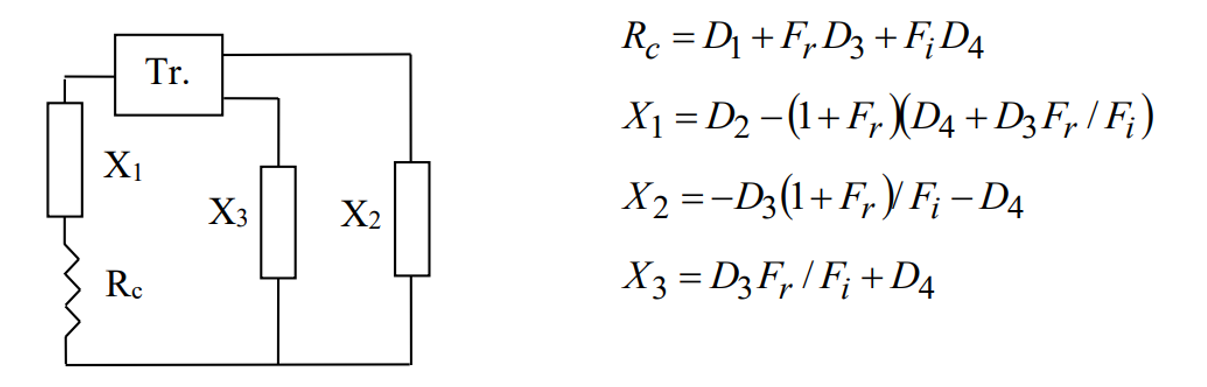

design4.Rc = D1 + real(F)*D3 + imag(F)*D4;
design4.X1 = D2 - (1+real(F))*(D4 + D3*real(F)/imag(F));
design4.X2 = -D3*(1+real(F))/imag(F) - D4;
design4.X3 = D3*real(F)/imag(F) + D4;

if design4.X1 > 0
    design4.L1 = design4.X1/omega0;
else
    design4.C1 = -1/(omega0*design4.X1);
end

if design4.X2 > 0
    design4.L2 = design4.X2/omega0;
else
    design4.C2 = -1/(omega0*design4.X2);
end

if design4.X3 > 0
    design4.L3 = design4.X3/omega0;
else
    design4.C3 = -1/(omega0*design4.X3);
end

% Design 5

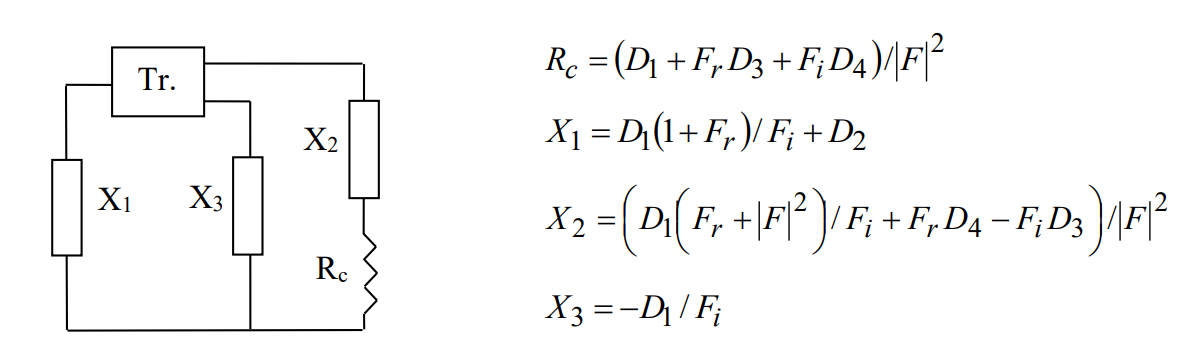

design5.Rc = (D1 + real(F)*D3 + imag(F)*D4)/abs(F)^2;
design5.X1 = D1*(1+real(F))/imag(F) + D2;
design5.X2 = (D1*(real(F) + abs(F)^2)/imag(F) + real(F)*D4 - imag(F)*D3)/abs(F)^2;
design5.X3 = -D1/imag(F);

if design5.X1 > 0
    design5.L1 = design5.X1/omega0;
else
    design5.C1 = -1/(omega0*design5.X1);
end

if design5.X2 > 0
    design5.L2 = design5.X2/omega0;
else
    design5.C2 = -1/(omega0*design5.X2);
end

if design5.X3 > 0
    design5.L3 = design5.X3/omega0;
else
    design5.C3 = -1/(omega0*design5.X3);
end

% Design 6

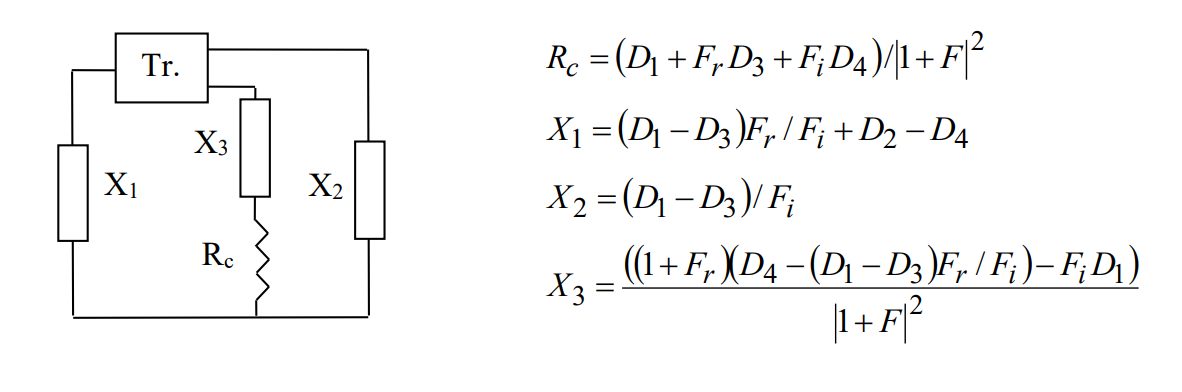

design6.Rc = (D1 + real(F)*D3 + imag(F)*D4)/abs(1+F)^2;
design6.X1 = (D1 - D3)*real(F)/imag(F) + D2 - D4;
design6.X2 = (D1 - D3)/imag(F);
design6.X3 = ((1+real(F))*(D4 - (D1 - D3)*real(F)/imag(F)) - imag(F)*D1)/abs(1+F)^2;

if design6.X1 > 0
    design6.L1 = design6.X1/omega0;
else
    design6.C1 = -1/(omega0*design6.X1);
end

if design6.X2 > 0
    design6.L2 = design6.X2/omega0;
else
    design6.C2 = -1/(omega0*design6.X2);
end

if design6.X3 > 0
    design6.L3 = design6.X3/omega0;
else
    design6.C3 = -1/(omega0*design6.X3);
end


design1

design1 = struct with fields:
    Gc: 400.0627e-003
    B1: 4.8544e+000
    B2: 314.3268e-003
    B3: -296.0129e-003
    Rc: 2.4996e+000
    X1: 205.9973e-003
    X2: 3.1814e+000
    X3: -3.3782e+000
    L1: 16.3927e-012
    L2: 253.1679e-012
    C3: 23.5560e-012


design2

design2 = struct with fields:
    Gc: 1.6686e-003
    B1: 1.7051e-003
    B2: -134.3082e-006
    B3: -559.7781e-006
    Rc: 599.2932e+000
    X1: 586.4882e+000
    X2: -7.4456e+003
    X3: -1.7864e+003
    L1: 46.6712e-009
    C2: 10.6879e-015
    C3: 44.5457e-015


design3

design3 = struct with fields:
    Gc: 1.4730e-003
    B1: 297.1581e-003
    B2: 18.8738e-003
    B3: -18.4267e-003
    Rc: 678.9042e+000
    X1: 3.3652e+000
    X2: 52.9836e+000
    X3: -54.2691e+000
    L1: 267.7950e-012
    L2: 4.2163e-009
    C3: 1.4663e-012


design4

design4 = struct with fields:
    Rc: 7.0606e+003
    X1: -800.3811e+000
    X2: 2.0532e+003
    X3: -2.0453e+003
    C1: 99.4245e-015
    L2: 163.3913e-009
    C3: 38.9071e-015


design5

design5 = struct with fields:
    Rc: 501.4009e+000
    X1: 130.4095e+000
    X2: 222.8528e+000
    X3: -3.8678e+000
    L1: 10.3777e-009
    L2: 17.7341e-009
    C3: 20.5742e-012


design6

design6 = struct with fields:
    Rc: 580.1716e+000
    X1: 2.1719e+003
    X2: 11.7813e+000
    X3: 72.6158e+000
    L1: 172.8314e-009
    L2: 937.5230e-012
    L3: 5.7786e-009
